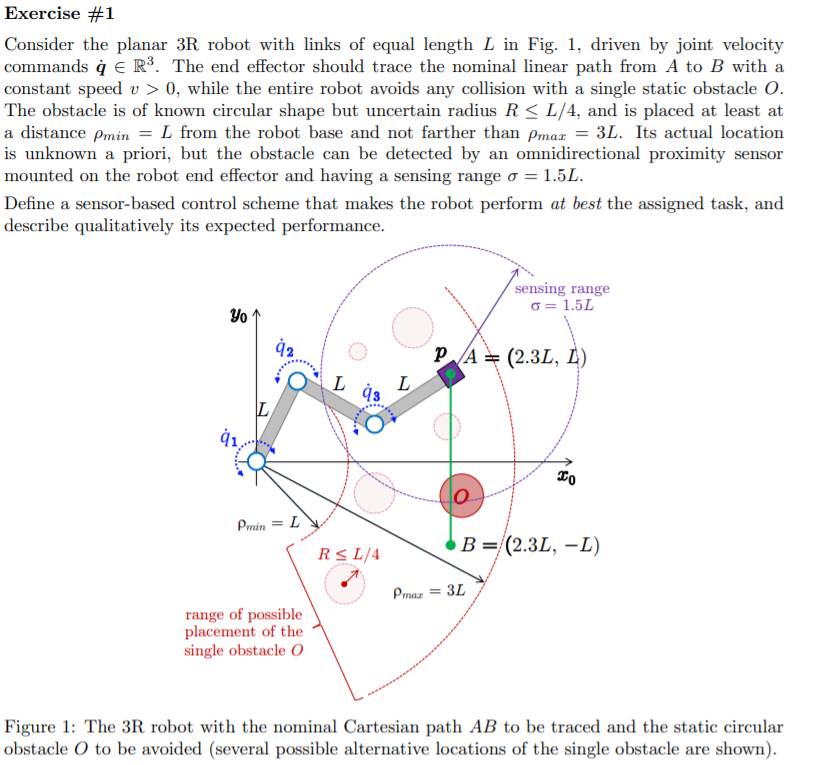

%done by hand


## 2

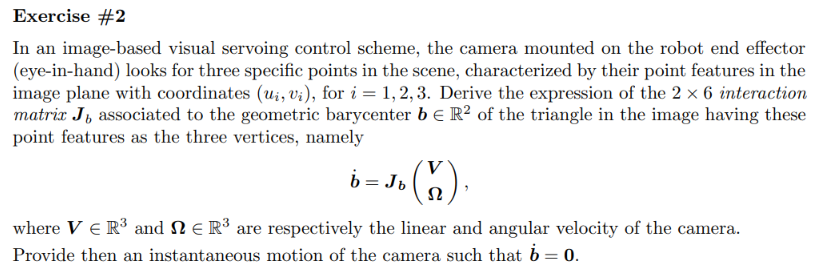

% clc;clear;
% [J_camera,velocities,V,OMEGA]=gen_interaction_matrix(3)

% % J_b=(J_camera{1}+J_camera{2})/2
% J_b=(J_camera{1}+J_camera{2}+J_camera{3})/3
% OMEGA=[0,0,0]' 
% vel_=J_b*[V;OMEGA]

% resn=(simplify(null(J_b),'steps',105)) %one ofthis solutions works well also
% res1=simplify(J_b*resn(:,1),'steps',15)

% % J_b(1,1)
% % J_b(1,3)
% % simplify(J_b(1,3)/J_b(1,1))

% % res=solve([vel_==0;V~=0],[V])

% % % res.Omega_1
% % res.V_1
% % res.V_2
% % res.V_3

## 3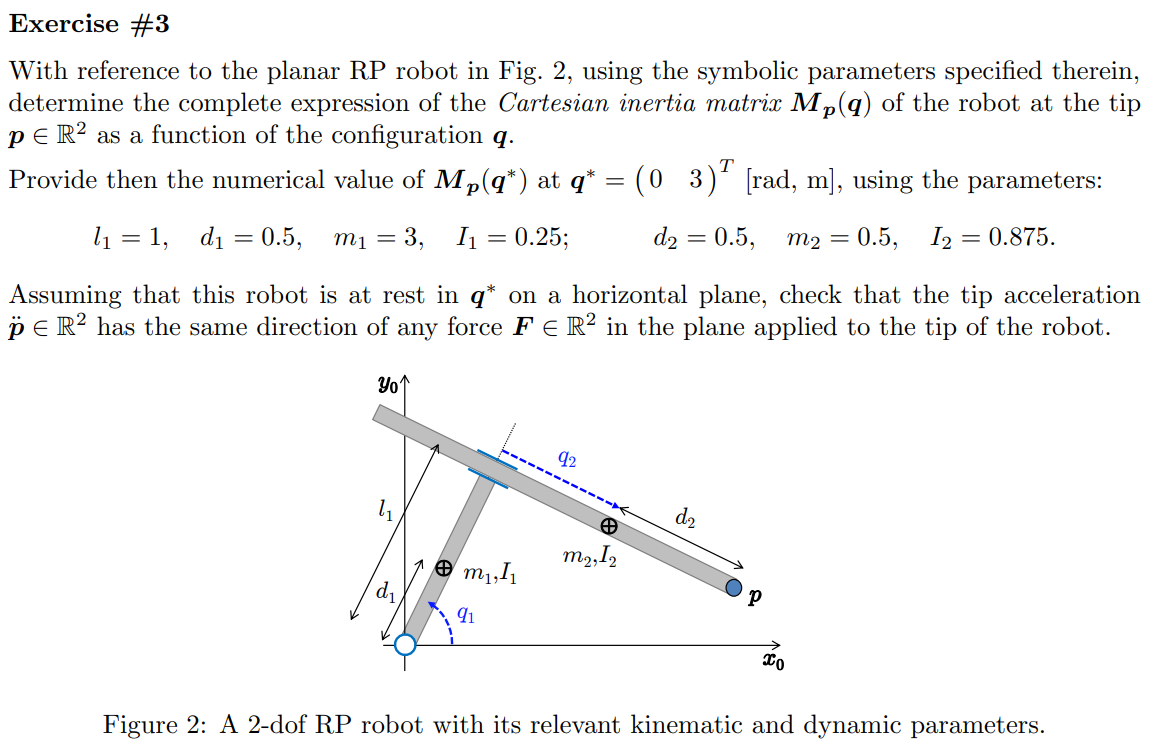

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,0];
% R2Robot=['rp';'xy';sigmaD]
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[-q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)
% 

% Pc
% 
% M
% Trans.PTotal

% J=jacobian(Pc(:,2),z.q)

% J_inv=simplify(pinv(J))
% Mp=(J_inv'*M*J_inv)

% 

% % [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% % cac
% % S

% % [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)

% q_=[0,3]'
% l_=[1,z.l(2)]'
% dc_=[0.5,0.5]'
% m_=[3,0.5]'
% I_=[0.25,0.875]'
% to_replace=[z.q;z.l;z.dc;z.m;z.I]
% to_replace_=[q_;l_;dc_;m_;I_]

% 

% Mp_=vpa(subs(Mp,to_replace,to_replace_))

% J_=subs(J,to_replace,to_replace_)
% M_=subs(M,to_replace,to_replace_)
% J_inv_=pinv(J_)

% Mp_1=(J_inv_'*M_*J_inv_)
% Mp_2=pinv(J_*pinv(M_)*J_') %in this case are exactly the same bu the right way to compute mp is the this method, pay attention!

% F=sym('F_',[3,1],'real')
% p_ddot_=pinv(Mp_)*F

## 4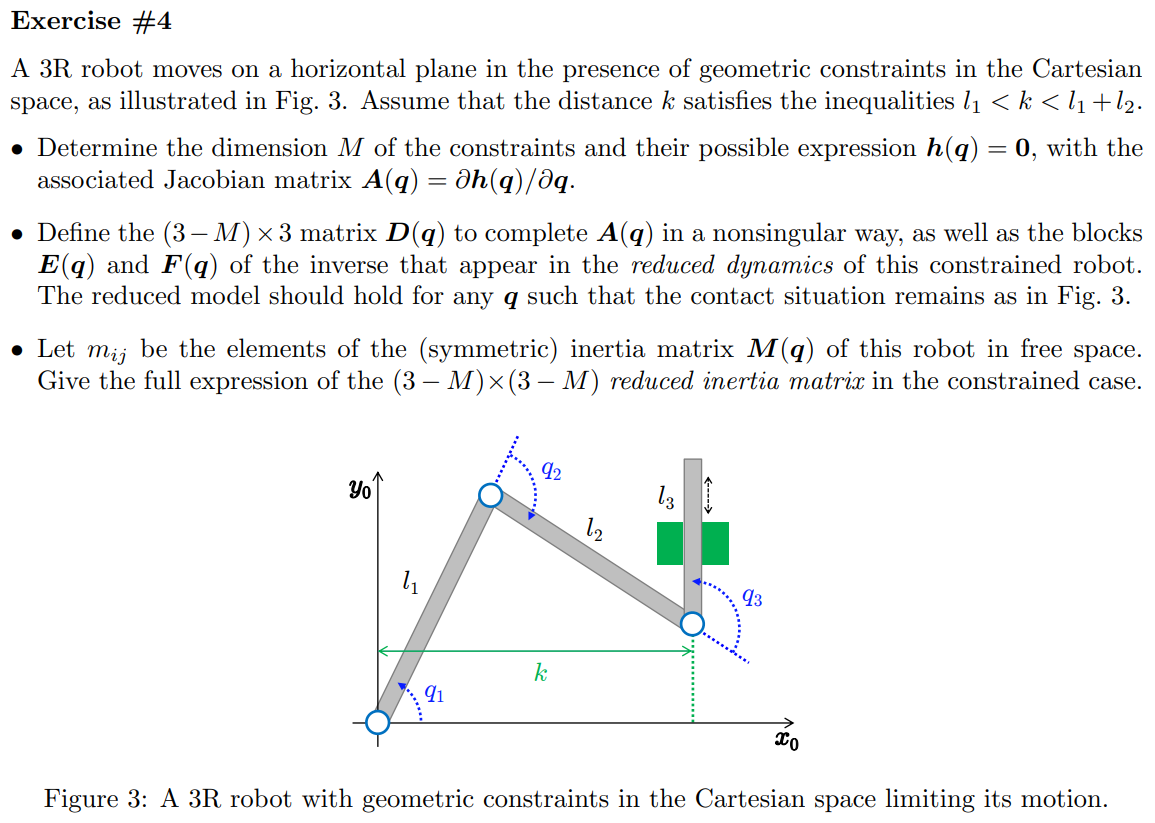

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [1,0];
R2Robot=['pr';'yx';sigmaD]

R2Robot = 3×2 char array
    'pr'
    'yx'
    ' '


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                


[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                

si falla aquí está el error


$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2} \end{array}\right)$$

$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & {\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: (I2*q_dot_2^2)/2 + (m1*q_dot_1^2)/2 + (m2*(dc2^2*q_dot_2^2 + 2*c2*dc2*q_dot_1*q_dot_2 + q_dot_1^2))/2
    Ti: [(m1*q_dot_1^2)/2    (I2*q_dot_2^2)/2 + (m2*(dc2^2*q_dot_2^2 + 2*c2*dc2*q_dot_1*q_dot_2 + q_dot_1^2))/2]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: q_2
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: (m2*(dc2^2*q_dot_2^2 + 2*cos(q_2)*dc2*q_dot_1*q_dot_2 + q_dot_1^2))/2 + (I2*q_dot_2^2)/2 + (m1*q_dot_1^2)/2
                     Ti: [(m1*q_dot_1^2)/2    (m2*(dc2^2*q_dot_2^2 + 2*cos(q_2)*dc2*q_dot_1*q_dot_2 + q_dot_1^2))/2 + (I2*q_dot_2^2)/2]
                      M: [2×2 sym]


Pc

$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

vc

$$vc = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

T

$$T = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

M

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

Trans.PTotali(:,2)

$$ans = \left(\begin{array}{c} l_{2}\,\cos\left(q_{2}\right)\\ q_{1}+l_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$S = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

cac

$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,q_{1}\,\left(m_{1}+m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

$$PE\_short = g_{0}\,q_{1}\,\left(m_{1}+m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,q_{1}\,\left(m_{1}+m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

U = 1×2 cell array
    {[g0*m1*q_1]}    {[g0*m2*(q_1 + dc2*sin(q_2))]}


$$g\_q\_short = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$PE\_short = g_{0}\,q_{1}\,\left(m_{1}+m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

k=sym('k','real')

$$k = k$$

A_sym=sym('A',[n,n],'real')

$$A\_sym = \left(\begin{array}{cc} A_{1,1} & A_{1,2}\\ A_{2,1} & A_{2,2} \end{array}\right)$$

h=[sum(z.q)-pi-2;Trans.PTotali(1,2)-k]

$$h = \left(\begin{array}{c} q_{1}+q_{2}-\pi -2\\ l_{2}\,\cos\left(q_{2}\right)-k \end{array}\right)$$

D_int=Trans.PTotali(2,2)

$$D\_int = q_{1}+l_{2}\,\sin\left(q_{2}\right)$$

A=jacobian(h,z.q)

$$A = \left(\begin{array}{cc} 1 & 1\\ 0 & -l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

D=jacobian(D_int,z.q)

$$D = \left(\begin{array}{cc} 1 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

## Finding D

A_sym2=A_sym;
A_sym2(1:2,:)=A

$$A\_sym2 = \left(\begin{array}{cc} 1 & 1\\ 0 & -l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

A_sym2(3,:)=D

$$A\_sym2 = \left(\begin{array}{cc} 1 & 1\\ 0 & -l_{2}\,\sin\left(q_{2}\right)\\ 1 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

det(A_sym2)

Error using sym/det (line 24)
Matrix must be square.

simplify(det(A_sym2),'steps',15)

[dyn_red]=dynamics_reduction(h,D,z)

dyn_red.M_red

## reduced M

M_sym=sym('M_',[n,n],'real')
to_collect=[sin(z.q(1)+z.q(2)),sin(z.q(1))]



r_side_M=(collect(simplify(M_sym*dyn_red.F),to_collect))%,to_collect2)
M_red=simplify(dyn_red.F'*M_sym*dyn_red.F)

simplify(M_red,'steps',150)


% to_collect2=[1/sin(z.q(2)),sin(z.q(1)+z.q(2))^2,sin(z.q(1))^2]
% to_collect2=[sin(z.q(1))^2,sin(z.q(1)+z.q(2))^2,(l(1)*l(2)/sin(z.q(2)))^2]
temp_factor=(l(1)^2)*(l(2)^2)*sin(q(2))^2
M_red2=simplify(simplify(dyn_red.M_red))
% 
% to_collect2=[sin(z.q(1))^2,sin(z.q(1)+z.q(2))^2,sin(z.q(1)+z.q(2)),sin(z.q(1))]%,sin(z.q(1)+z.q(2))^2,(l(1)*l(2)/sin(z.q(2)))^2]
to_collect2=[sin(z.q(1)+z.q(2)),sin(z.q(1)),l']
(collect(simplify(M_red2),to_collect2))

## 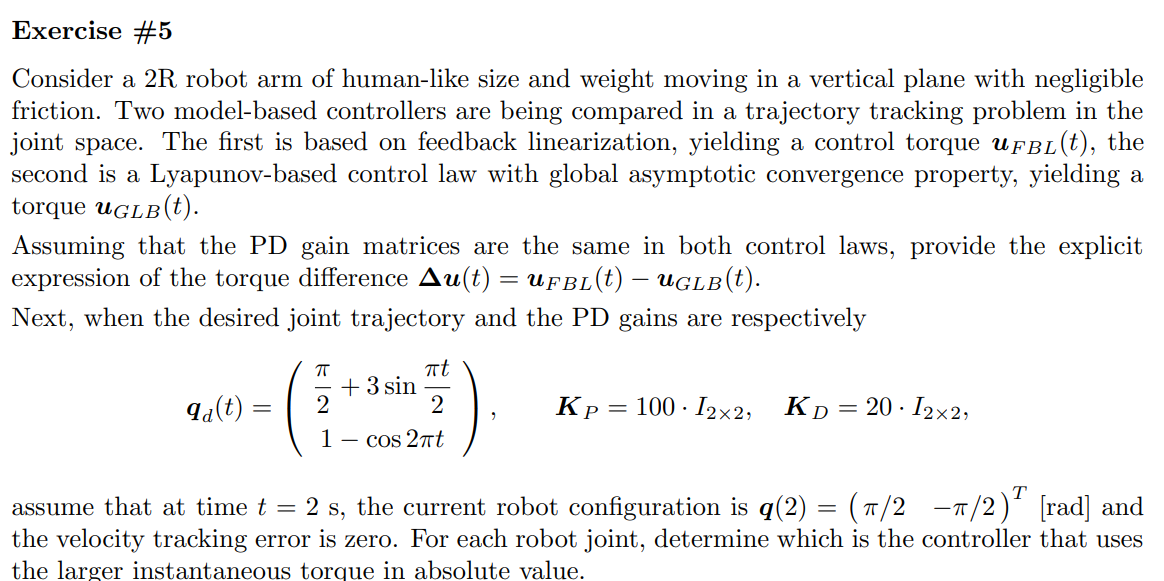

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [1,1];
R2Robot=['rr';'xx';sigmaD]
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table
% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[-q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

% 
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)
% 

Pc
% 
M
% Trans.PTotal

% J=jacobian(Pc(:,2),z.q)

% J_inv=simplify(pinv(J))
% Mp=(J_inv'*M*J_inv)

% 

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

cac
S

isMotor=false
[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor);

% [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)
[All, dynamicParameters, aM] = getDynamicParameters3([M,S,g_q],z.q,[z.q_dot],2);

Msubs=All(:,1:n)
Ssubs=All(:,n+1:2*n)
Gsubs=All(:,2*n+1)
aM

t=sym('t','real')
q_d         =[pi/2+3*sin(pi*t/2),1-cos(2*pi*t)]'
q_d_dot     =simplify(diff(q_d))

t_=2
q_      =[pi/2,-pi/2]'

% q_d_    =[pi/2+3*sin(pi*t_/2),1-cos(2*pi*t_)]'

% l_=[1,z.l(2)]'
% dc_=[0.5,0.5]'
% m_=[3,0.5]'
% I_=[0.25,0.875]'
to_replace=[z.q;t]
to_replace_=[q_;t_]

q_d_=(subs(q_d,to_replace,to_replace_))
q_d_dot_=(subs(q_d_dot,to_replace,to_replace_))
q_dot_ =q_d_dot_
% q_d_dot_  =[0,0]'
e_=q_d_-q_

e_dot_=q_d_dot_-q_dot_

to_replace=[z.q;z.q_dot;t]
to_replace_=[q_;q_dot_;t_]

M_=vpa(subs(Msubs,to_replace,to_replace_))
S_=vpa(subs(Ssubs,to_replace,to_replace_))

K_D=diag([20,20])
K_P=diag([100,100])

K_res_=((K_D*e_dot_+K_P*e_))

% 50*pi
delta_u_=((M_-eye(size(M)))*K_res_)